clear;
% R_load = 2*10^8;
% R_load = 2*10^9;
R_load = 2*10^10;
gain = 218*1.95*4;

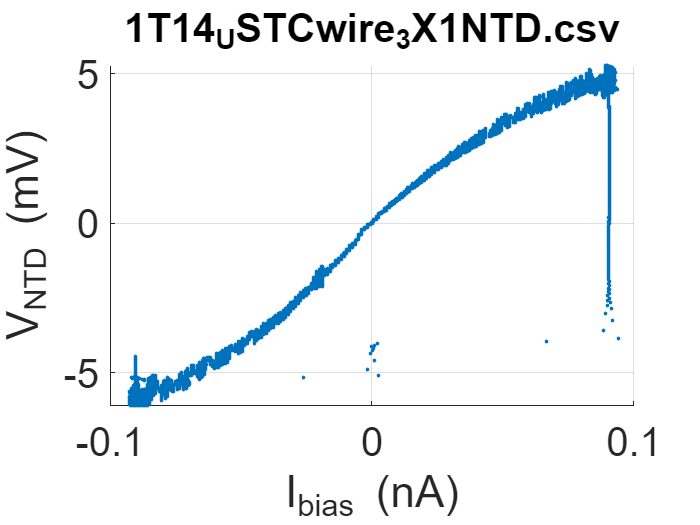

% Get the filenames and path of the selected CSV files
[filename, path] = uigetfile('*.csv', 'Select CSV file');

% If the user clicked cancel, return
if isequal(filename,0)
   return;
end

% Read the CSV file
data = readmatrix(fullfile(path, filename));

% import the data
V_bias = data(5:end,4);
V_out = data(5:end,2);
I_bias = V_bias *10^9 / R_load;
V_NTD = V_out *10^9 / gain;

% Draw the figure with x axis V_bias (V) and y axis V_out
figure;
scatter(I_bias, V_NTD/10^6,'filled','SizeData',5);
% scatter(V_bias, V_out,'filled','SizeData',5,'MarkerFaceAlpha',.1,'MarkerEdgeAlpha',.1);
xlabel('I_{bias} (nA)');
ylabel('V_{NTD} (mV)');
% ylim([-1.5 1.5]);
grid on;
set(gca,'FontSize',24); % set font size of axis numbers
title(filename,FontSize=24);

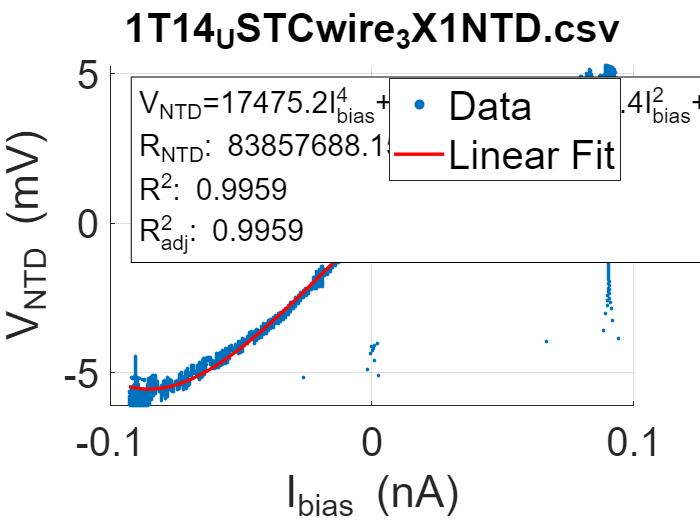

x_range = [min(I_bias) max(I_bias)];
% x_range = [-4.2 4.2];
x = I_bias(I_bias >= x_range(1) & I_bias <= x_range(2));
y = V_NTD(I_bias >= x_range(1) & I_bias <= x_range(2));

% Linear fit the data and show the fit parameters in a box
p = polyfit(x, y, 4);

% calculate the R^2
y_fit = polyval(p,x);
y_resid = y - y_fit;
SSresid = sum(y_resid.^2);
SStotal = (length(y)-1) * var(y);
rsq = 1 - SSresid/SStotal;
rsq_adj = 1 - SSresid/SStotal * (length(y)-1)/(length(y)-length(p));

% print the result
text(0.05, 0.95, sprintf('V_{NTD}=%.1fI_{bias}^4+%.1fI_{bias}^3+%.1fI_{bias}^2+%.4fI_{bias}+%.1f \nR_{NTD}: %.4f \nR^2: %.4f \nR_{adj}^2: %.4f', p(1)/10^6, p(2)/10^6,p(3)/10^6,p(4)/10^6,p(5)/10^6,p(4),rsq,rsq_adj), 'Units', 'normalized', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', 'BackgroundColor', 'w', 'EdgeColor', 'k',FontSize=18);

% Plot the fitted line
hold on;
fplot(@(x) (p(1)*x.^4+p(2)*x.^3+p(3)*x.^2+p(4)*x+p(5))/10^6,x_range,'r','LineWidth',2);
% scatter(x, y_fit/10^6);
legend('Data', 'Linear Fit','Fontsize',24);
hold off;

fprintf('%.4f\n', p(4));

83857688.1583
